# Social LEAP Estimates Animal Poses (SLEAP) using MATLAB

[**SLEAP**](http://sleap.ai) is an open source deep-learning based framework for estimating positions of animal body parts.

This example demonstrates application of the [**SLEAP Toolbox**](https://github.com/talmolab/sleap-matlab) to import SLEAP models trained using TensorFlow 2 into MATLAB and to make estimates of body part keypoints on a sample video dataset of multi-animal (social) behavior. 

The example loads and concatenates two deep learning pretrained models: the *centroid *and *top-down *models. The centroid model provides confidence heatmaps for presence of animal(s) in a frame. Animals are then cropped and sent individually to the top-down model which estimates keypoints for each animal.

## Identify sample data and pretrained model files 

The [SLEAP Toolbox](https://github.com/talmolab/sleap-matlab) includes sample data and pretrained models to illustrate the animal pose estimation workflow: 

sampleVideoFile = fullfile(pwd, "sample_data", "test_clip.mp4");
centroidNetFile = fullfile(pwd, "pretrained_models", 'centroids.200823_193403.UNet');
topdownNetFile = fullfile(pwd, "pretrained_models", 'topdown.200823_204048.UNet');

all(arrayfun(@exist,[sampleVideoFile centroidNetFile topdownNetFile])) % test all files are found

ans = logical
   1


## Load & Configure Top-Down Pose Prediction

### Load pretrained model configuration files 

The  `model.loadNetConfig()` function loads the configuration files associated with each pretrained model: 

centroidConfig = sleap.model.loadNetConfig(centroidNetFile);
topdownConfig = sleap.model.loadNetConfig(topdownNetFile);

The structure variable outputs contain parameters about the model components, how they were trained, and the training results:

all(isstruct([centroidConfig topdownConfig])) % test all model configuration files were successfully read

ans = logical
   1


The `.data `field for each pretrained model contains parameters which connect the models to the input & intermediate image size: 

inputScale = centroidConfig.data.preprocessing.input_scaling; % image scaling factor for first-stage centroid model
bboxSize = [topdownConfig.data.instance_cropping.crop_size topdownConfig.data.instance_cropping.crop_size]; % intermediate image size for second-stage top-down model

### Load pretrained model network files 

The `model.loadNet()` functions import SLEAP TensorFlow pretrained models into MATLAB:  

centroidNet = sleap.model.loadNet(centroidNetFile);

topdownNet = sleap.model.loadNet(topdownNetFile);

The outputs are [`DAGNetwork`](https://www.mathworks.com/help/deeplearning/ref/dagnetwork.html) objects defined by the Deep Learning Toolbox: 

all(isa([centroidNet topdownNet],"DAGNetwork"))

ans = logical
   1


### Configure inter-stage processing parameters

Between the two stages (centroid prediction & top-down animal pose prediction), some postprocessing (or pre-processing relative to the second stage) is needed.

The centroid model predicts the probabilities (0-1) a pixel corresponds to the centroid of an animal instance. A probability threshold should be set to help compute the crop regions passed to the second stage animal pose prediction network: 

centroidPredictionThreshold = 0.3; 

## Predict animal poses via batch inference

Prediction of animal poses is most efficient when the input video frames are processed in batches, as demonstrated in the following code sections. 

### Compose networks into a single model

For batch prediction of animal pose keypoints, it's most convenient to combine the two component networks  into a composite `DAGNetwork `object. The SLEAP toolbox function `sleap.model.topdown.compose `performs this operation: 

composedNet = sleap.model.topdown.compose(centroidNet, topdownNet, inputScale, bboxSize, centroidPredictionThreshold, centroidConfig, topdownConfig);

The `model.topdown.compose` function uses [custom layers](https://www.mathworks.com/help/deeplearning/ug/define-custom-deep-learning-layers.html) to implement the intermediate processing between the stages to allow single network prediction. 

### Run batch inference on whole video

Prediction of animal poses simply requires calling the `predict `method of the composite model created above, inputting the whole sample video & specifying the batch size (`MiniBatchSize`) parameter: 

vds1 = sleap.data.makeVideoDatastore(sampleVideoFile);
vds = transform(vds1, @(x) preprocessImage(x, inputScale));
[Y, numAnimalsPerFrame] = composedNet.predict(vds, 'MiniBatchSize', 16);
Y = squeeze(Y);

### Visualize cropped animal pose keypoint predictions 

The three-dimensional output array `Y `contains the predicted keypoint positions, one per frame and per animal`: `

vr = VideoReader(sampleVideoFile);
isequal(length(Y), vr.numFrames * numAnimalsPerFrame)

ans = logical
   0


To visualize the results better, a cropped output video will be created from the global bounds of keypoint predictions for each image dimension: 

xmin = min(min(Y(:,1,:)));
xmax = max(max(Y(:,1,:)));
ymin = min(min(Y(:,2,:)));
ymax = max(max(Y(:,2,:)));

The output video can be optionally saved to a movie file using the [`VideoWriter`](http://viz.showpeaks%20visualization%20function%20i) object: 

save_video = false;
savedir = pwd;

Create, show, and write cropped keypoint visualization:  

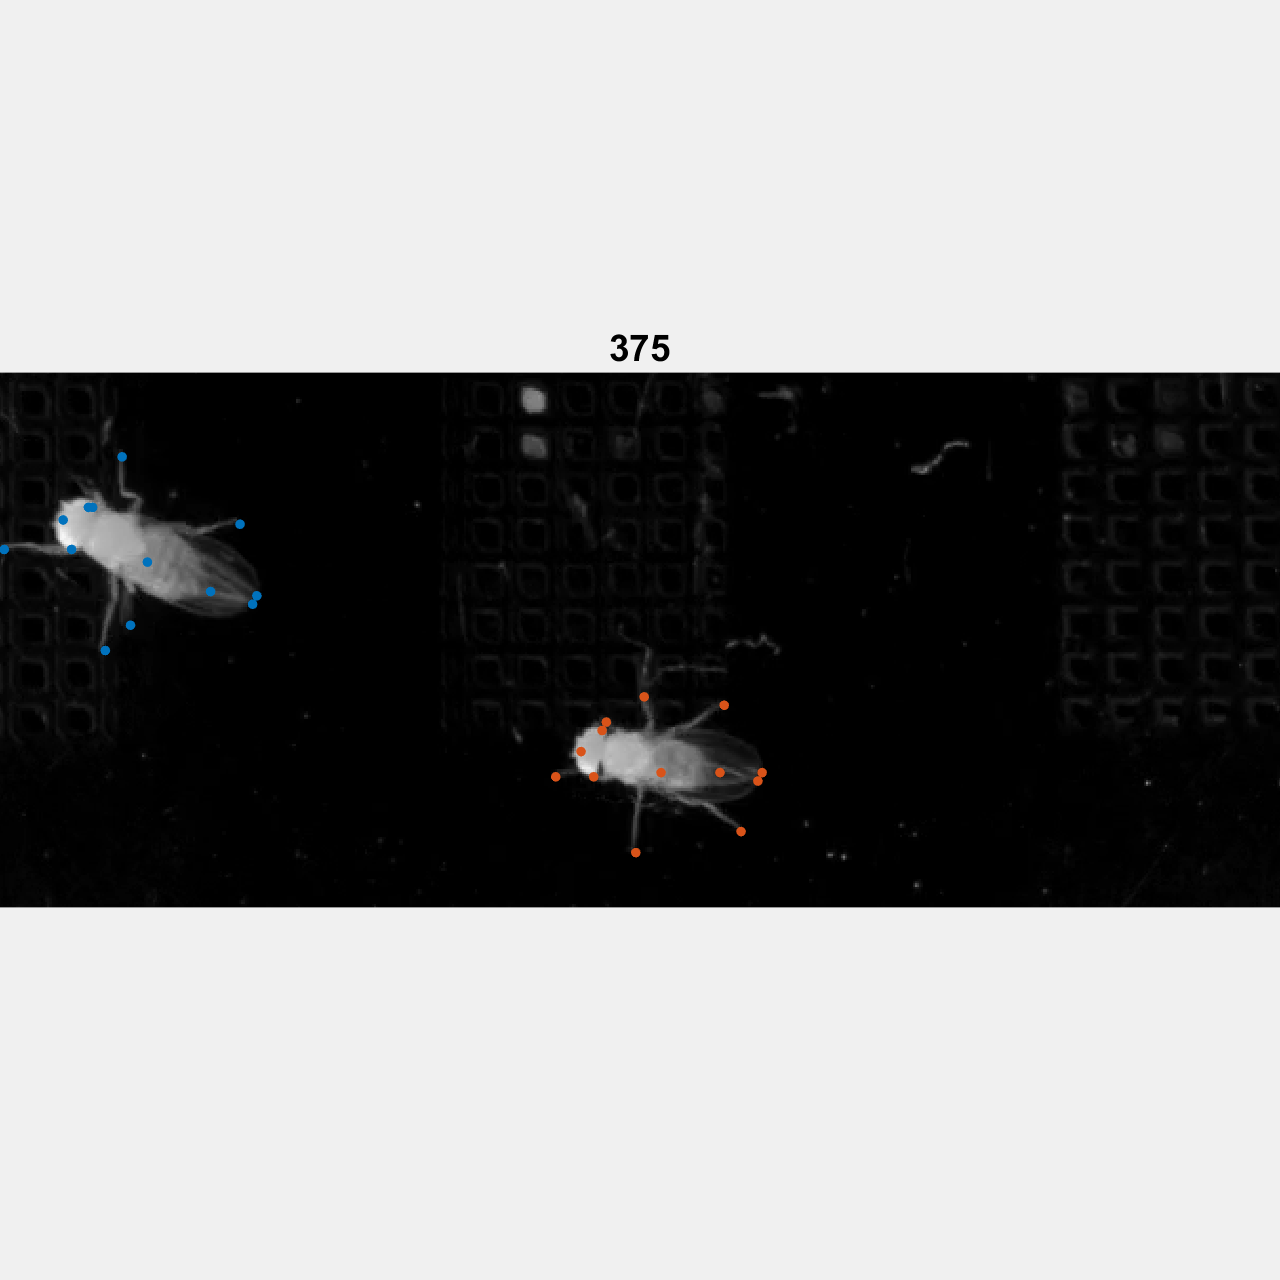

% Create visualization figure
f2 = figure("Visible","on");
f2.Name = "Batch animal pose prediction results";

% Optional output video file with cropping & keypoint visualization
if save_video
    v = VideoWriter(fullfile(savedir,'OutputVideoFile'),'MPEG-4');
    open(v)
end

% Update visualization figure frame-by-frame with pose prediction data
animalCnts = [0; cumsum(numAnimalsPerFrame)];
for frameIdx = 1:vr.NumFrames
    thisImg = vr.read(frameIdx); % re-use video reader from above
    thisImg = preprocessImage(thisImg);
    thisImgPeaks = Y(:,:,animalCnts(frameIdx)+1:animalCnts(frameIdx+1));
    sleap.viz.showPeaks(thisImg, thisImgPeaks)
    f2.Position(3) = round(size(thisImg,1)/4)*2;
    f2.Position(4) = round(size(thisImg,2)/4)*2;
    f2.Children.XLim = [xmin xmax];
    f2.Children.YLim = [ymin ymax];
    title(string(frameIdx));
    if save_video
        I = getframe;
        writeVideo(v,I.cdata)
    else
        drawnow
    end
end


if save_video
    close(v)
else
    % do nothing
end

## Predict animal poses step-by-step via two-stage online inference

This following optional code section exposes the SLEAP animal pose estimation process in greater detail, while illustrating an online (frame by frame) inference workflow which is important for some applications. For each frame of the sample video, the following operations are performed sequentially: 

- **read** the frame's image data (from a [`fileDatastore`](https://www.mathworks.com/help/matlab/datastore.html) representing the sample data files`)`

- **preprocess** the image to match the scale of the centroid model & support gpu prediction (`single` type)

- [`predict`](https://www.mathworks.com/help/deeplearning/ref/dlnetwork.predict.html) the animal locations with the centroid prediction model

- **postprocess **the centroid predictions to produce animal instance cropped images to the animal pose prediction model 

- [`predict`](https://www.mathworks.com/help/deeplearning/ref/dlnetwork.predict.html) pose keypoint locations with the top-down animal pose prediction model

- **visualize **inferred animal keypoints overlaid on the image frame (via the `viz.showPeak `visualization function)

This sequence includes two deep learning inference (`predict`) operations, hence it is a two-stage inference versus the single stage inference used in the batch prediction above.

twoStageFramewisePrediction = false; % Check box & run this section for two-stage frame-by-frame prediction

if twoStageFramewisePrediction
    vr = VideoReader(sampleVideoFile);
    vds1 = sleap.data.makeVideoDatastore(sampleVideoFile);
    vds = transform(vds1, @(x) preprocessImage(x)); % define preprocessing function

    f1 = figure("Visible","on");
    f1.Name = "Online animal pose prediction";

    while hasFrame(vr)

        % Read frame
        thisImg = read(vds); % applies pre-processing

        % Stage 1: Centroid Prediction
        thisImgCentroids = centroidNet.predict(imresize(thisImg,inputScale));

        % Stage 1 Postprocessing
        centroidPeaks = sleap.image.impeaksnms(thisImgCentroids, centroidPredictionThreshold);
        centroidPeaks = centroidPeaks / inputScale;
        centroidPeaks = centroidPeaks * centroidConfig.model.heads.centroid.output_stride;
        crops = arrayfun(@(i)centerCrop(thisImg,centroidPeaks(i,1),centroidPeaks(i,2),bboxSize), 1:size(centroidPeaks,1), 'UniformOutput',false);

        % Stage 2: Top-down Pose Prediction
        cropConfmaps = cellfun(@(x)topdownNet.predict(x), crops, 'UniformOutput',false);

        % Stage 2 Postprocessing
        cropPeaks_ = cellfun(@findAllPeaks, cropConfmaps, 'UniformOutput',false);
        cropPeaks = cat(3,cropPeaks_{:});
        cropPeaks = cropPeaks * topdownConfig.model.heads.centered_instance.output_stride;

        thisImgPeaks = cropPeaks + permute(centroidPeaks, [3 2 1]) - (bboxSize * 0.5);

        % Visualize predicted pose estimates
        sleap.viz.showPeaks(vr.readFrame, squeeze(thisImgPeaks))
        drawnow

    end
end

## Helper functions

function I = preprocessImage(I, inputScale)
if nargin < 2 || isempty(inputScale)
    inputScale = 1; %Default
end

I = rgb2gray(I);
I = single(I) / 255;
I = imresize(I, inputScale);
end

function crop = centerCrop(img, x, y, bboxSize)
    R = imref2d(bboxSize, [x - bboxSize(1)/2, x + bboxSize(1)/2], [y - bboxSize(1)/2, y + bboxSize(2)/2]);
    crop = imwarp(img,affine2d(),'OutputView',R);
end

function peaks = findAllPeaks(confmaps, minThresh)
    if nargin < 2; minThresh = 0.2; end
    C = size(confmaps,3);
    peaks = NaN(C, 2);
    for c = 1:C
        [point, val] = sleap.image.imargmax(confmaps(:,:,c));
        if val >= minThresh
            peaks(c,:) = point;
        end
    end
end
